# IPV Assignment 3 (week 3) 

## **Q1: for Part 5 (un)sharpening: **The two (un)sharping filters (“**a-laplace(a)**” and “**2*a - gaussf(a)**”) are not the same. Can you explain the difference of them? How are they alike? 

To explain that, we need to understand what is the meaning of this two operations and how to implement them.

**Understanding 2*a - gaussf(a)**

**Gaussian Filter**

Gaussian filter was deeply explained on the assignment of last week. Its main features are:

- **High-frequency component filter: **The Gaussian filter masks the details in the image, being a good filter for noise reduction and smoothing/blurring.

- **Linear filter: **Uses a 2D Normal Distribution to create its convolution matrix.

- **Sigma parameter: **Determines the strength of the filter, usually the matrix convolution size is calculed using this value. As sigma increase, the output get molt blurred.

**Multiplication by a scalar**

The first operation that we are doing here is `2*a`. When we multiplicate an Image using an scalar, we are changing the relative intensity of the pixels. The relative intensity is directly related to the contrast, because we use the differences of intensity between some areas of the image to distinguish different intensity areas as different objects in the picture.

We prepare the environment:

clear
addpath('/lib/dip/common/dipimage');  % Adds path to the used images
dip_initialise;  % Initilialize libraries


DIPlib 2.9 (Oct 16 2017 - Release [on Linuxa64 (with OpenMP)])
    Scientific Image Analysis Library
    Quantitative Imaging Group, Delft University of Technology 1995-2017
    info@diplib.org


dipIO 2.9 (Oct 16 2017 - Release)
    File I/O library for DIPlib
    Quantitative Imaging Group, Delft University of Technology 1999-2017
    info@diplib.org



dipsetpref('imagefilepath','/home/amt/IPV/');  % Optional: sets default image saving/loading folder

For example, in the image cermet we can see that the difference between the maximum and minimum intensity in the picture is 30:

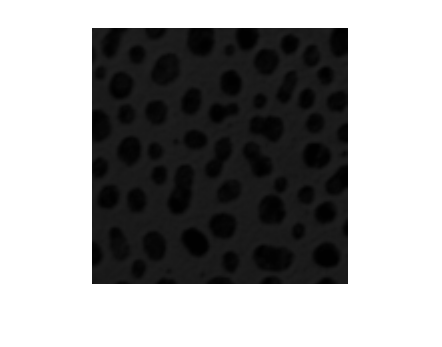

a = readim('cermet.tif');
imshow(dip_array(a));

disp(max(max(dip_array(a))) - min(min(dip_array(a))))

   30



In this case we are losing a lot of possible contrast since we are using 8 bits for intensity encoding (allowing a range up to 2^8 different intensities) but we are just using a range of 30 values to represent it.

But if we multiply the image using an scalar the difference between the maximum and the minimum intensity in the image gets multiplied too.

disp(max(max(3*a)) - min(min(3*a)))

    90



The bigger is the intensity in a pixel, the bigger it will be in the output because of the nature of the multiplication operation. That means that light colors will get much lighter than dark colors do after applying this operation. For example, the zones of the image with small values (darker areas) will still have small values after get multiplied, but light colours with higher intensities will be easily approaching to white color. Meaning that the intensity of lighter pixels gets saturated, losing contrast between light areas and making them more uniform. That can only happen in images that are really light, so the `cermet` is not a good example. We need to multiplicate the image many times before that happens:

saturating_scalar = 2^8 / max(max(dip_array(a))) + 1  % For a uint8 image --> 2^8 max value

saturating_scalar = uint8
9

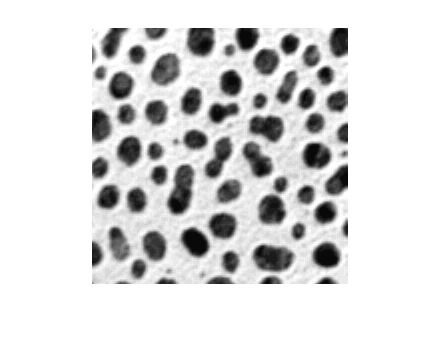

imshow(dip_array(a)* saturating_scalar);

In this case the contrast between objects and the background is bigger.

We can see also how the histogram of the image evolves with the multiplication by an scalar, making the points on it more disperse.

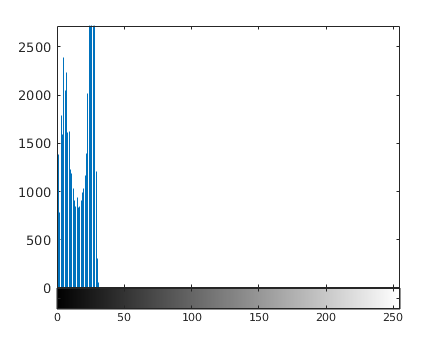

imhist(dip_array(a));

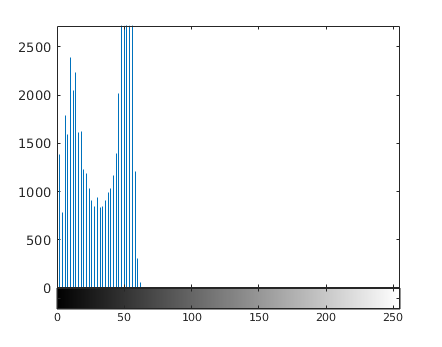

imhist(dip_array(a) * 2);

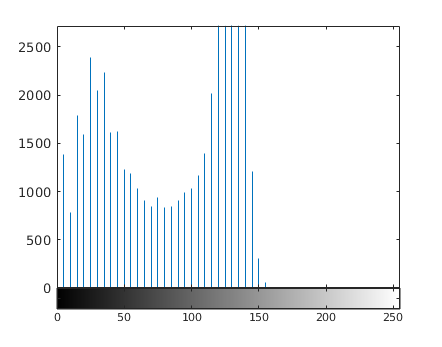

imhist(dip_array(a) * 5);

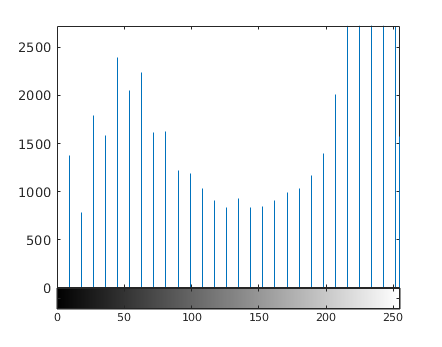

imhist(dip_array(a) * saturating_scalar);

Finally, to compare, the histogram of the output from the histogram equalization function.

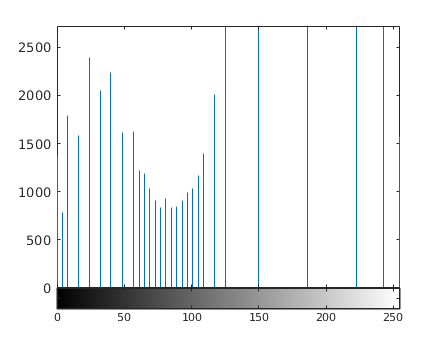

imhist(histeq(dip_array(a)));

You can notice that the distribution of the intensities is similar between the output of `histeq `and `a * 5.`

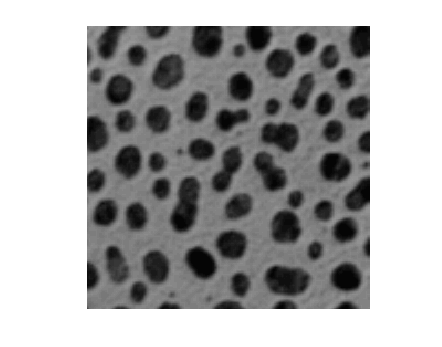

imshow(dip_array(a) * 5);

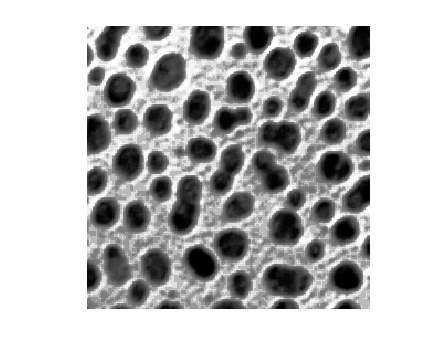

imshow(histeq(dip_array(a)));

But is similar just for the darker pixels, forming the dark objects of the image.

Let's try the given operation on a lighter image with more contrast:

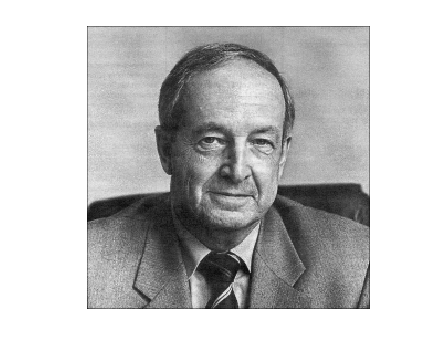

b = readim('devoogd.tif');
imshow(dip_array(b));

disp(max(max(dip_array(b))));

   243



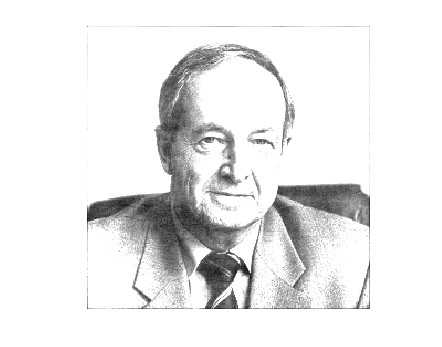

imshow(dip_array(b) * 2);

We can see how the effect of the multiplication is bigger on images with a wider range of intensities.

So, we can conclude saying that the multiplication of an scalar by an image:

- Produces an image with **a bigger difference between pixels of different intensity**. 

- The lighter areas can be saturated easily in lighter photos, **losing the contrast between the pixels forming them**.

- At the same time, **contrast between light and dark areas increase.**

**Meaning of the substraction between the multiplication and the Gaussian filtered image**

First, we need to be aware of :


$$\lim_{\sigma \to 0} \;2*a-\mathrm{gaussf}\left(a,\sigma \right)\;=a$$


So, the difference between the input image $a$ and the output of our operation depends entirely on $\sigma$.

To see the effect of the filter we are going to try different values of sigma 

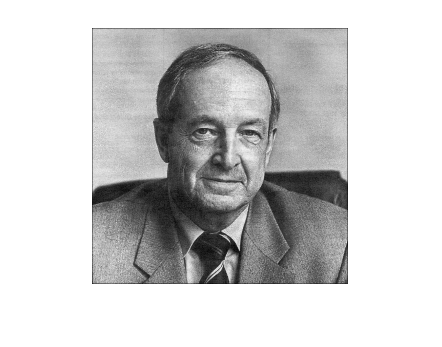

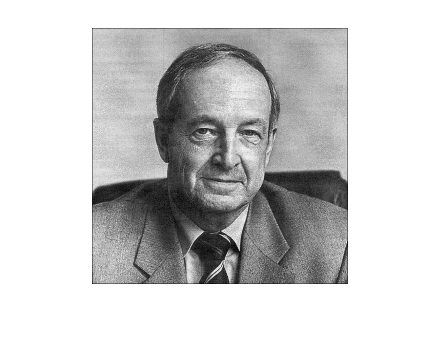

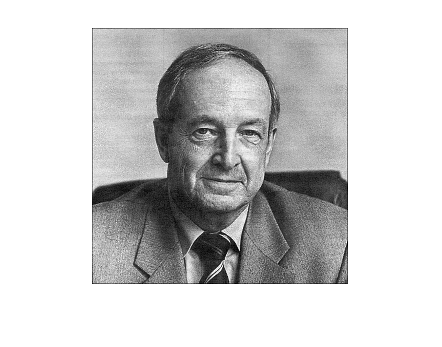

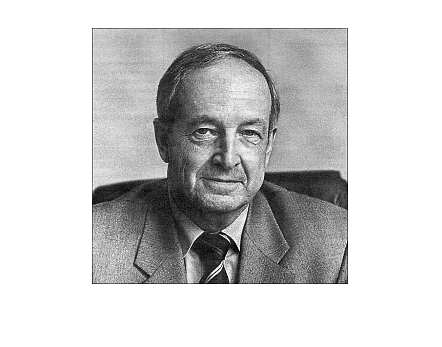

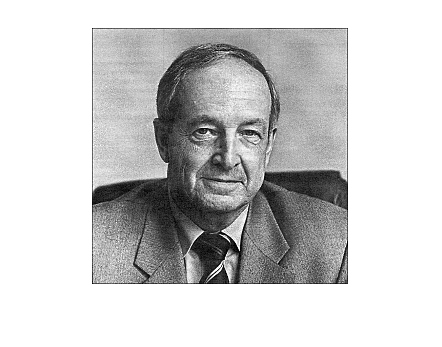

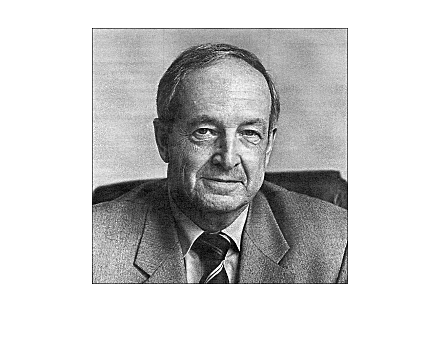

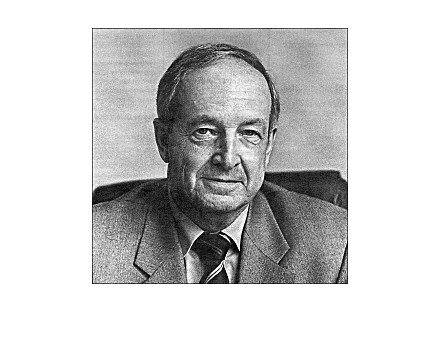

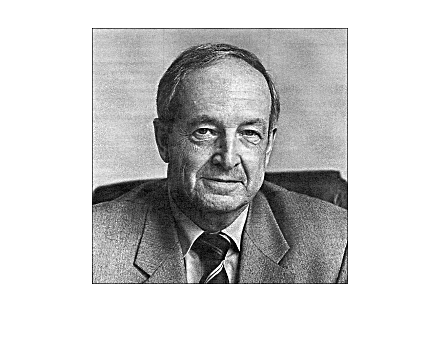

%variables
interval = 0.25;
finalvalue = 3;

X = zeros([1/interval+2 size(A)], 'uint8'); % Explicit initialization

counter = 1;
for t = 0:interval:finalvalue
    X(counter, :, :) = uint8(dip_array(double(dip_array(b)) * 2 - gaussf(dip_array(b), t)));
    counter = counter + 1;
end

% Show them
for i = 1:size(X, 1)-1
    tmp = X(i, :, :);
    figure;
    imshow(reshape(tmp, [size(tmp, 2) size(tmp, 3)]));
end

    isequal(reshape(X(1, :, :), [size(X(1, :, :), 2) size(X(1, :, :), 3)]), dip_array(b))

ans = logical
   1


Effectively, the output is the same when  $\sigma =0$.

So the effect that this operation produces is the **sharpening of the images. **We can notice that the bigger is $\sigma$ the more sharpening is produced in the image. 

This happens because the Gaussian filter specially changes the pixels that are on the edges. This pixels have different intensities in the neighbourhood, so white pixels and black pixels on the edges are going to be converted to a gray colour that is in between. We can see then when we substract that the white areas in the edges now are more white, and the dark areas on the edges now are more dark. This increase de contrast specially in the edges but we can see also how the noise increase.

**Conclusion**

- Sharpening filter.

- Substracting generates the same image in the homogeneous areas and more contrast in the edges. 

- On edges, dark areas get subtracted by bigger numbers getting darker intensities. The opposite happens for brighter areas on the edges.

**Understanding a-laplace(a)**

The Laplacian is a mathematical operator used to calculate the rate of changes in a function given a certain point of the function. To calculate it, we need to use function derivatives.

In our case we don't have a function, just a matrix of intensities, so we are going to use the **discrete version of the laplacian operator.**

This version of the laplacian operator can be implemented using a convolution matrix. Also we can distinguish between the inward edges or the outward edges. We can use a different convolution matrix for each case.

outward_edges_conv = [0 1 0; 1 -4 1; 0 1 0];
inward_edges_conv = [0 -1 0; -1 4 -1; 0 -1 0];
inward_edges = imfilter(dip_array(b), inward_edges_conv);
outward_edges = imfilter(dip_array(b), outward_edges_conv);

So we can see that the areas of the image with bigger rate change appear in white while homogeneous areas are completely black.

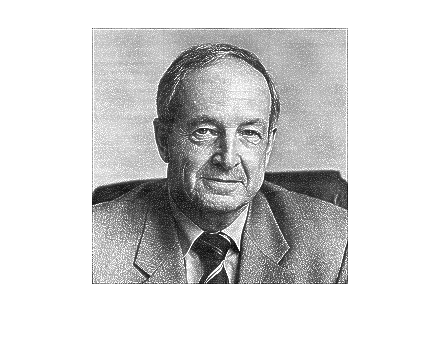

imshow(dip_array(b) + inward_edges);

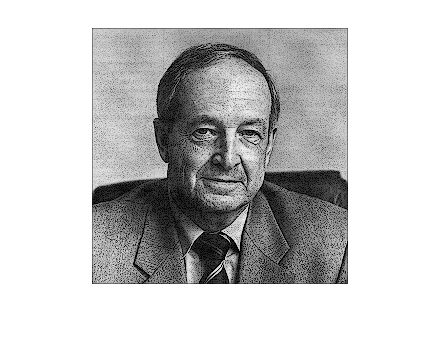

imshow(dip_array(b) - outward_edges);

We can see that the operation produces a lot of noise so a applying a smoothing filter before is recommended.

Now we are going 

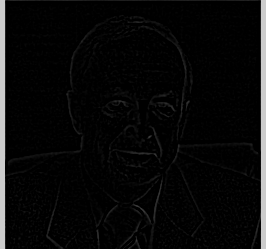

title = "laplacian"

% Different values on the second argument
dipshow(laplace(b))

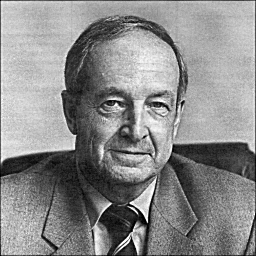

% Difference with the original photo
dipshow(b - laplace(b))

b % compare to b

When substracting the two images, the edges are going to have higher numbers on the laplacian picture, so the result will darker, creating more contrast in the edges. The homogeneous areas will not be changed substantially.

**Conclusions**

- **Sharpening filter.**

- Changes the intensity on the edges using the laplacian and then substracts, changing the pixels on the edges generating more contrast.

**Differences**

We can notice that the two images use a simiilar principle: They try to highlight some parts of the photos and then substract it from the original. They focus on the edges to create contrast.

There is some differences. The first thing is that using **2*a -gaussf(a)** generates just a little bit of noise and also your image is duplicated before substracting. The gaussian filter produce output containing a lot of information from the original, so we need to multiply by two before substracting or our image will be black. 

The Gaussian filter is a low-pass filter so when you substract from a duplicated photo instead of conserving low-frequency components, you et the high-frequency components, those that give the details and the sharpening in the image.

In the **a-laplace(a)** we can notice that the output of the laplacian just highlights the edges so we are losing a lot of "information" from the picture. A good feature also is that homogeneous areas in the image are going to be mainly black or really dark, so the areas that are not edges are not going to be changed.

Finally, they can be used in similar contexts, but **2*a-gaussf(a) **gives us less noise and more possibilities using $\sigma$.

**References**

- Dogra A, Bhalla P. Image Sharpening By Gaussian And Butterworth High Pass Filter. Biomed Pharmacol J 2014;7(2). Available [here](http://biomedpharmajournal.org/?p=3274).

- Wikipedia, [Partial Derivative](https://en.wikipedia.org/wiki/Partial_derivative), [Image derivative](https://en.wikipedia.org/wiki/Image_derivatives)

- [Gaussian and Laplacian filters](https://www.swarthmore.edu/NatSci/mzucker1/e27_s2016/filter-slides.pdf)

- [Image derivative](http://mccormickml.com/2013/02/26/image-derivative/)

- [Filter types](http://spatial-analyst.net/ILWIS/htm/ilwisapp/filters_types_gradient_or_derivative_filters_technical_information.htm)

## **Q2: Make your own applications and demo for image fitering**

On this section we are going to compare two different egde detection filters.

One of them will be a linear filtering using a 3 by 3 kernel and the second one will be a commonly used edge detection known as *Canny Edge Detector*. Lastly we will try to re-create such algorithm.

I = imread('rice.tif');

imshow(I), title('Original')
eKernel = [-1 -1 -1; -1 8 -1; -1 -1 -1];
eI = imfilter(I, eKernel);
imshow(eI), title('Kernel edge detection')
cI = edge(I,'Canny');
imshow(cI), title('Canny edge detection')

Here we can see that the Canny detection results with a more shaprened edge with less noise edge detection. This mainly due to the **Non-maximum suppression function** used in it. This function only uses the most dominant pixel of the neighbourhood of edges as an edge. In addition Hysteresis Thresholding also plays a role in the edge deteciton, including a low and a high threshold on the function, the final edge detection will result with a complete outline of the objects. These two functions will be explained in futher detail in the next section.

These are the steps taken in Canny edge detection:

- Smooth image with Gaussian filter

- Apply derivative of Gaussian

- Find magnitude and orientation of gradient

- Non-maximum suppression

- Hysteresis Thresholding

Now that we know the basis of Canny edge detection, we can program our own edge detection.

We will start by applying the Guassian filter on the image to smooth it.

J = imgaussfilt(I, 0.1);

In this step we calculte the gradient of the smoothed picture.

This step is also know as the Sobel operator, which is another well known edge detection algorithm. The Sobel operator computes an approximation of the gradient magnitude of an image. This is font by firtsly calculating the directional gradient on the x direction (which will result on an 'edge deteciton' going vertically) and a directional gradient on the y direction (result on 'edge detection' of horizontal lines). These results can be found on the image below.

[Gx,Gy] = imgradientxy(J);
imshowpair(Gx, Gy, 'montage'), title('Directional Gradient x (Left) & Directional Gradient y (Right)');

Once we calculate the directional gradient of both axis we can easily calulate the gradient magnitude with the *Pythagoras Theorem*: * * 

- Gradient module: $\textrm{Gmag}=\;\sqrt{{\textrm{Gx}}^2 +{\textrm{Gy}}^2 }$ 

- Gradient direction: $\mathrm{Gdir}\;=\;\mathrm{arctan}\left(\frac{\mathrm{Gx}}{\mathrm{Gy}}\right)$.

The gradient magnitude reults on .... and the gradient direction results on ...

[Gmag,Gdir] = imgradient(Gx,Gy);
imshowpair(Gmag,Gdir,'montage'), title('Gradient Magnitude (Left) and Gradient Direction (Right)')

**Non-Maximum Suppresion**

K = Gmag;
for y = 1: size(K, 1)
    for x = 1: size(K, 2)
        if y == 0 || y == size(K, 1) -1 || x == 0 || x == size(K, 2) -1
            K(x, y) = 0;
        end
        if Gtheta == 0
            if K(x, y) <= K(x, y-1) || K(x, y) <= K(x, y+1)
                K(x,y) = 0;
            end
        end
        if Gtheta == 1
            if K(x, y) <= K(x-1, y+1) || K(x, y) <= K(x+1, y-1)
                K(x,y) = 0;
            end
        end
        if Gtheta == 2
            if K(x, y) <= K(x-1, y) || K(x, y) <= K(x+1, y)
                K(x,y) = 0;
            end
        end
        if Gtheta == 2
            if K(x, y) <= K(x-1, y-1) || K(x, y) <= K(x+1, y+1)
                K(x,y) = 0;
            end
        end
    end
end


**Hystersis Thresholding**

L = hysteresis3d(K, 0.355, 15, 4);
imshow(L), title('Self Canny edge detector')